# IBME CA#2 - Extracting Classification Features and Model Training for Gait Signals

***Reyhane Vahedi 810195498 ***

First we will need to download and store the data. The below functions are set up to download, store, and prepare the data for the purpose of plotting and dividing. 

%{ 
The functions are individually referenced in the parent pathway
function [varargout] = helperGaitImport(varargin)

load PNGait.mat;
    if nargin == 1
        idx = find(strcmp(pnames,varargin{1})); 
        x_out = x{idx};
        val_out = val{idx};
        varargout = {val_out,x_out};
    else
        varargout = {pnames};
    end

end
%% then we will be using the data to plot the recording of different data rows into comprehensible plots

function helperGaitPlot(patientStr)

    [val_out,x_out] = helperGaitImport(patientStr);

    figure;
    plot(x_out', val_out');
    legend('Left foot','Right foot');
    xlabel('Time (sec)');
    ylabel('mV');
    grid on
    title('Gait Signal Data');

end
%}

## Measure Inter-Stride Time Intervals

The dataset being analyzed contains force data collected during walking for patients with Amyotrophic Lateral Sclerosis (ALS) and a control group. ALS is a disease made famous by Lou Gehrig, Stephen Hawking, and the 2014 'Ice Bucket Challenge'.

Load and plot the first 30 seconds of gait signal data for one patient.

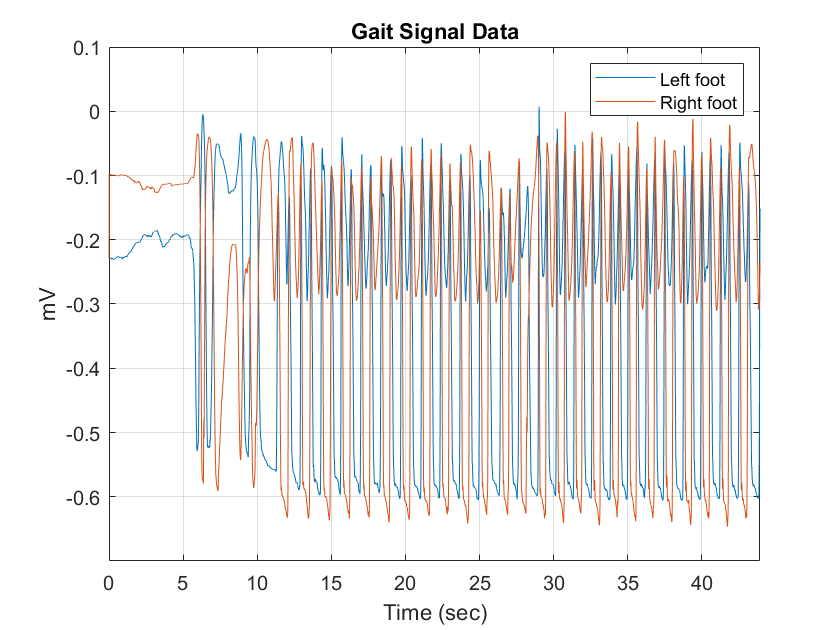

helperGaitPlot('als1m');
xlim([0 30])

Here we have used `midcross` to find the sharp changes for an ALS patient's recording and the proceeded to find and plot the location of each crossing for the left foot of an ALS patient. 

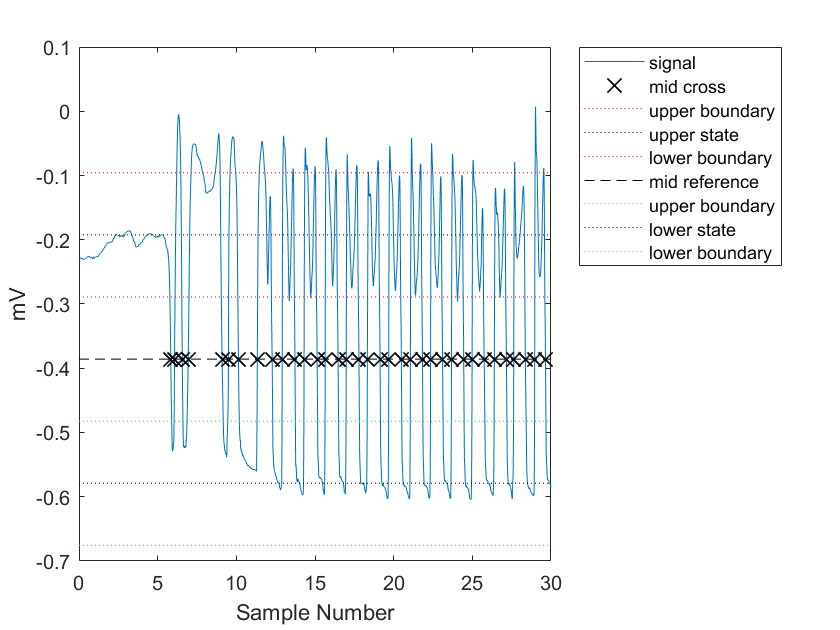

Fs = 300;
gaitSignal = helperGaitImport('als1m');
midcross(gaitSignal(1,:),Fs,'tolerance',25);
xlim([0 30])
xlabel('Sample Number')
ylabel('mV')

calculating the inter-stride times for a group of ten patients.

pnames = helperGaitImport();
for i = 1:10
  gaitSignal = helperGaitImport(pnames{i});
  IND2 = midcross(gaitSignal(1,:),Fs,'Tolerance',25);
  IST{i} = diff(IND2(9:2:end));   
  varIST(i) = var(IST{i});
end

Here we will plot the stride timing of each of these patients.

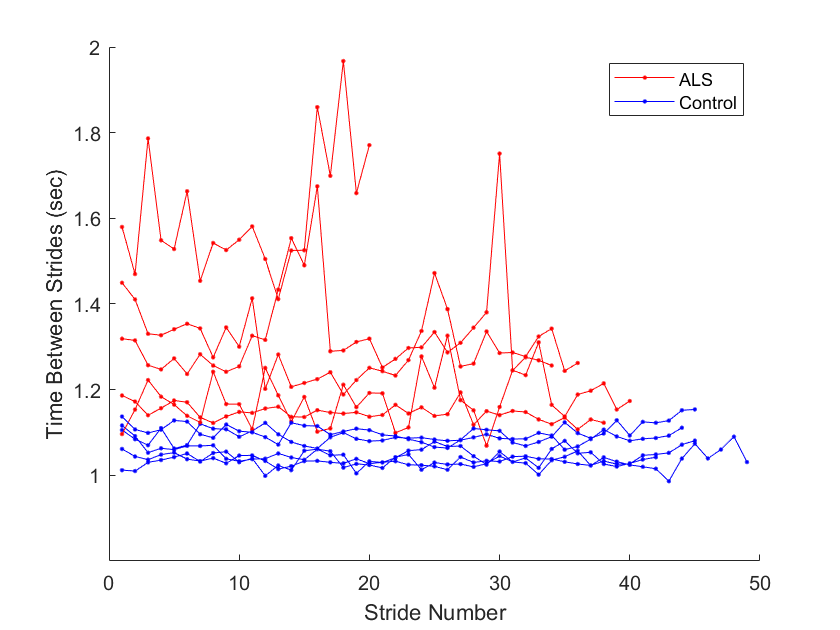

figure
hold on
for i = 1:5
  plot(1:length(IST{i}),IST{i},'.-r')
  plot(1:length(IST{i+5}),IST{i+5},'.-b')
end
xlabel('Stride Number')
ylabel('Time Between Strides (sec)')
legend('ALS','Control')

We can see that the variance of the inter-stride times is higher overall for the ALS patients.

## Measure Similarity of Walking Patterns

Here we will load the gait signal data segments from the imported database.

load PNGaitSegments.mat

The patient does not walk at the same rate throughout the record thus we will need to showcase a measure of the distance between segments by warping them to align them in time by using the dtw function.. 

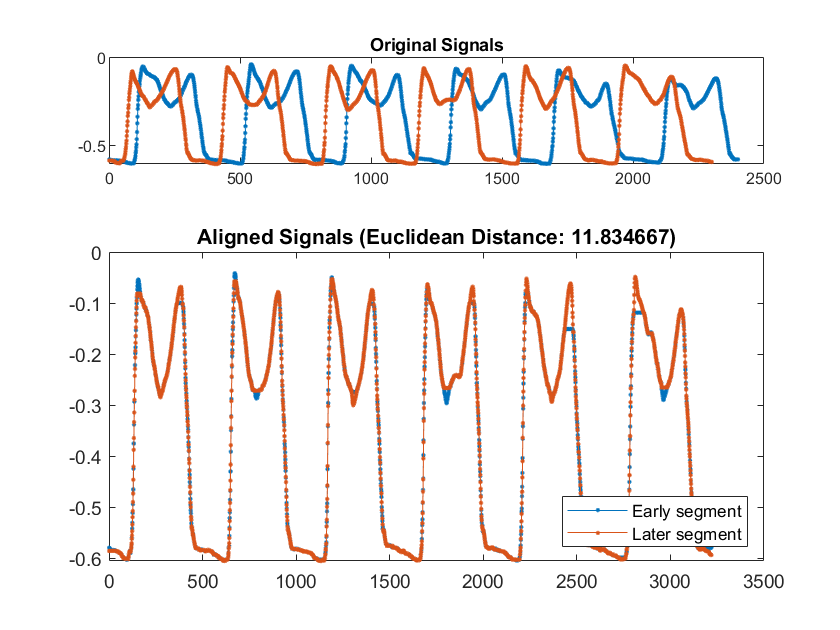

figure
dtw(sigsInitialLeft{1},sigsFinalLeft{1});
legend('Early segment','Later segment','location','southeast')

## Construct a Feature Vector to Classify Signals

Feature 1 was previously computed using `midcross and f`eature 2 is extracted  for the ALS patients and the control group.

feature1 = varIST;
feature2 = zeros(10,1);
for i = 1:length(sigsInitialLeft)
  feature2(i) = dtw(sigsInitialLeft{i},sigsFinalLeft{i});
end

In the end we will plot the features for ALS subjects and control subjects together as a means of comparison.

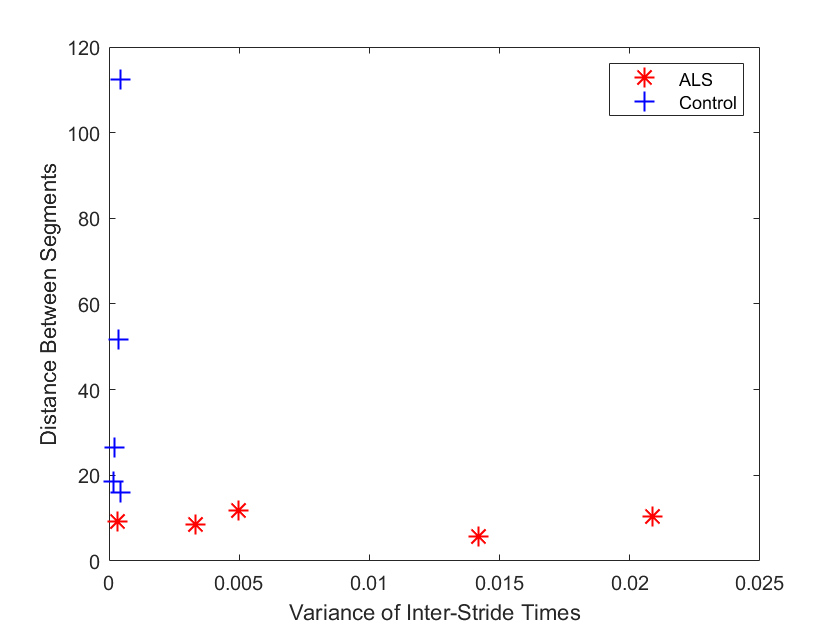

figure
plot(feature1(1:5),feature2(1:5),'r*',...
    feature1(6:10),feature2(6:10),'b+',...
    'MarkerSize',10,'LineWidth',1)
xlabel('Variance of Inter-Stride Times')
ylabel('Distance Between Segments')
legend('ALS','Control')

ALS patients seem to have a larger variance in their inter-stride times, but a smaller distance via `dtw` between segments. These features compliment each other and can be explored for use in a classifier such as a Neural Network or Support Vector Machine.

feature22 = [feature2.' 12.877 34.90 4.0567 17.322 67.852 102.603 4.209 78.36 43.842 9.68 65.5 39.720 107.024 4.892 5.762 7.043] 

feature22 =    11.8347    9.2837    8.4093   10.3687    5.6277   16.0877   26.5797   18.6690  112.3740   51.7110   12.8770   34.9000    4.0567   17.3220   67.8520  102.6030    4.2090   78.3600   43.8420    9.6800   65.5000   39.7200  107.0240    4.8920    5.7620    7.0430


feature11 = [feature1 0.006 0.0002 0.0191 0.06 0.0002 0.0007 0.005 0.00046 0.00023 0.008 0.0001 0.0003 0.00056 0.0301 0.005 0.0162]    

feature11 =     0.0050    0.0003    0.0033    0.0209    0.0142    0.0005    0.0002    0.0002    0.0005    0.0004    0.0060    0.0002    0.0191    0.0600    0.0002    0.0007    0.0050    0.0005    0.0002    0.0080    0.0001    0.0003    0.0006    0.0301    0.0050    0.0162


label=[1 1 1 1 1 0 0 0 0 0 1 0 1 1 0 0 1 0 0 1 0 0 0 1 0 0];
FEATURETABLE = [feature11 ; feature22; label]

FEATURETABLE =     0.0050    0.0003    0.0033    0.0209    0.0142    0.0005    0.0002    0.0002    0.0005    0.0004    0.0060    0.0002    0.0191    0.0600    0.0002    0.0007    0.0050    0.0005    0.0002    0.0080    0.0001    0.0003    0.0006    0.0301    0.0050    0.0162
   11.8347    9.2837    8.4093   10.3687    5.6277   16.0877   26.5797   18.6690  112.3740   51.7110   12.8770   34.9000    4.0567   17.3220   67.8520  102.6030    4.2090   78.3600   43.8420    9.6800   65.5000   39.7200  107.0240    4.8920    5.7620    7.0430
    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0    1.0000         0    1.0000    1.0000         0         0    1.0000         0         0    1.0000         0         0         0    1.0000         0         0


classificationLearner